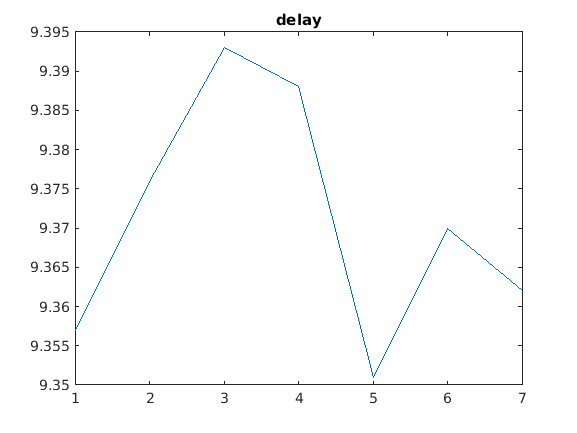

sentFile = ["1_3tab_noSEPA_sent.dat"
    "2_3tab_txSEPA_sent.dat"
    "3_3tab_rxSEPA_sent.dat"
    "4_3tab_tabSEPA_sent.dat"
    "5_3tab_tx-tabSEPA_sent.dat"
    "6_3tab_tx-tab-rxSEPA_sent.dat"
    "7_3tab_3tabSEPA_sent.dat"
    ];

sent_cnt = length(sentFile);

recvFile = ["1_3tab_noSEPA_recv.dat"
    "2_3tab_txSEPA_recv.dat"
    "3_3tab_rxSEPA_recv.dat"
    "4_3tab_tabSEPA_recv.dat"
    "5_3tab_tx-tabSEPA_recv.dat"
    "6_3tab_tx-tab-rxSEPA_recv.dat"
    "7_3tab_3tabSEPA_recv.dat"
    ];
    
recv_cnt = length(recvFile);

nretx = [];
result = [];
delay = [];
diversity = [];
snr= [] ;
rssi = [];

recv_len = [];
for cnt = 1:1:sent_cnt
    
    sent_array= csvread(sentFile(cnt));
    recv_array = csvread(recvFile(cnt));
    
    
    nretx = [nretx mean(sent_array(:,1))];
    result = [result mean(sent_array(:,2))];
    delay = [delay mean(sent_array(:,3))];
    
    diversity = [diversity mean(recv_array(:,1))];
    snr = [snr mean(recv_array(:,2))];
    rssi = [rssi mean(recv_array(:,3))];
    
    recv_len = [recv_len length(recv_array')];
end


plot(delay);
title("delay");

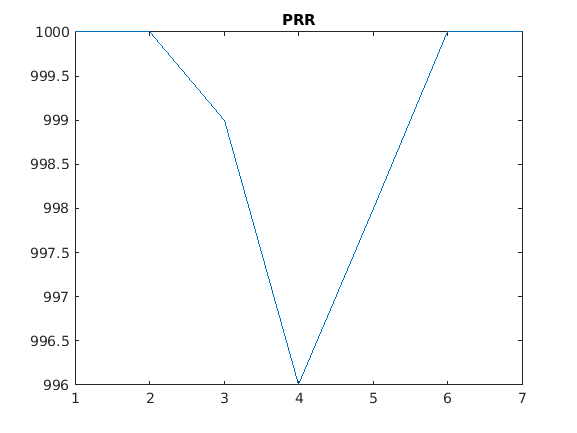

plot(recv_len);
title("PRR");

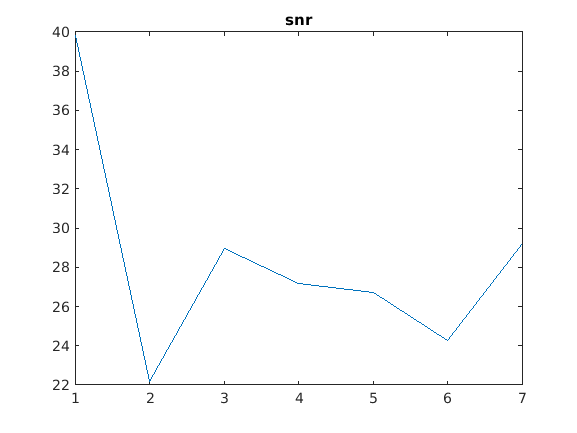

plot(snr);
title("snr");

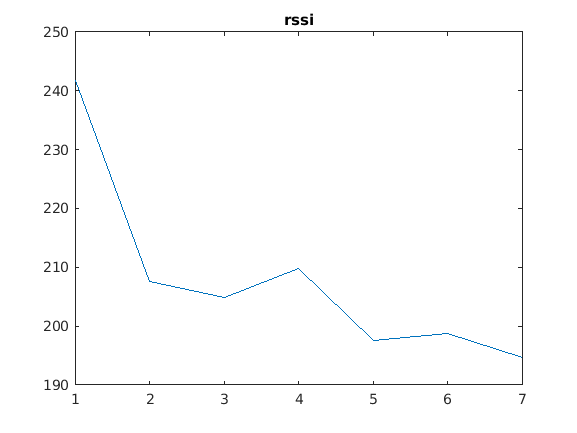

plot(rssi);
title("rssi");